# Part 1: Data Preparation and Feature Extraction

***Industrial Machinery Anomaly Detection***

# 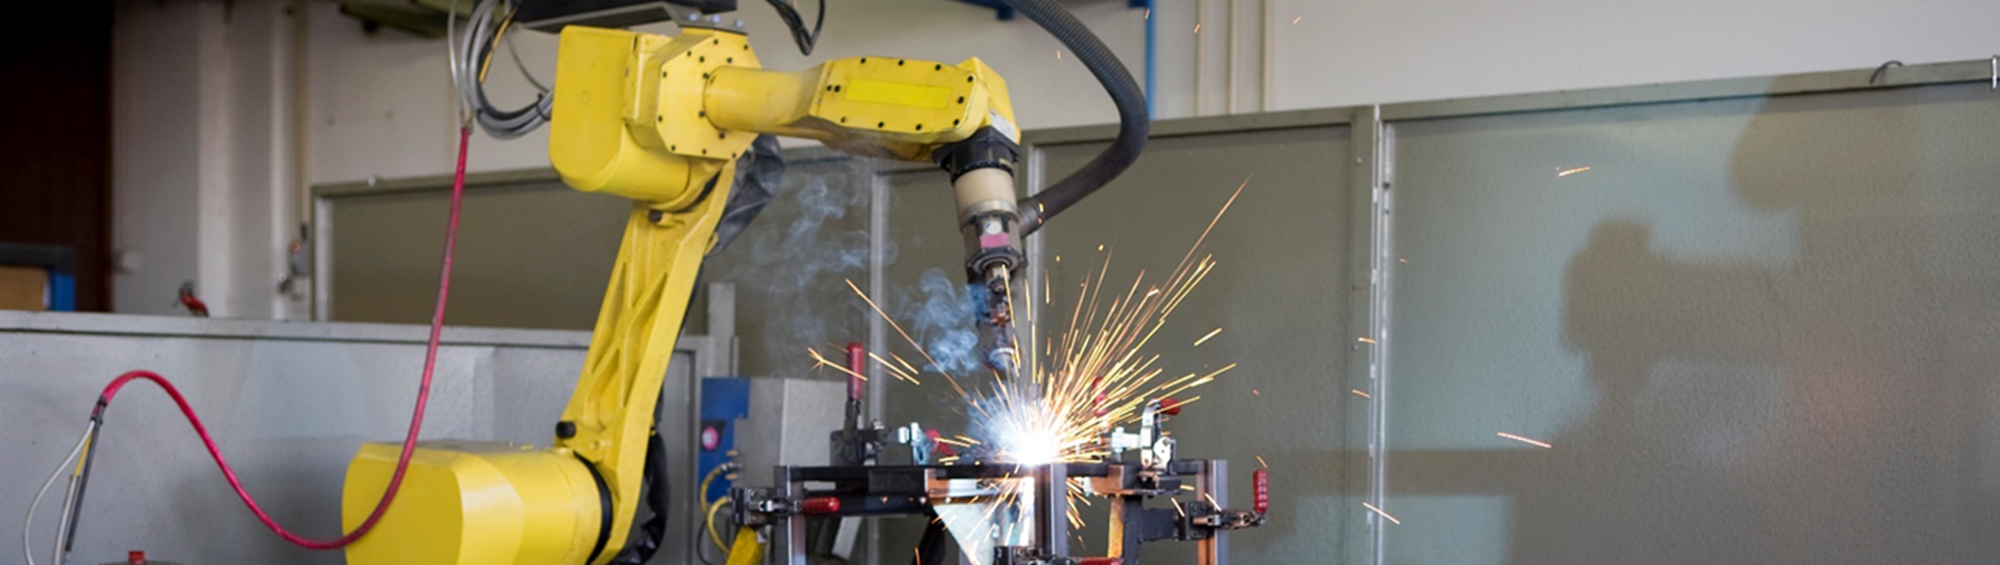

In this example, we train a Deep Learning Autoencoder is trained to detect if a machine is working normally or abnormally. It is trained on a set of 12 features, extracted from historical accelerometer data from "normal" operation, which was the time directly after a scheduled maintenance period. Features were computed from raw data using the [Diagnostic Feature Designer App](https://www.mathworks.com/help/predmaint/gs/explore-features-in-diagnostic-feature-designer.html) from the [Predictive Maintenance Toolbox](https://www.mathworks.com/products/predictive-maintenance.html)™.

This trained model is then used to monitor the machine over time. At a certain point the model output differs and drifts from the sensor data output. The more drift, the greater the indication that the machine is acting abnormally and requires maintenance.

## Load Data

We will start by loading the industrial machinery dataset, which contains three-channel accelerometer data from before and after maintenance. Each dataset corresponds to a label: when the label is 1, this indicates the data was collected **after **maintenance. We can assume that since maintenance was (hopefully) performed properly, that all of the "after" data is healthy. When the label is -1, this indicates the data was collected **before **maintenance. In this case, we the machine was taken offline for maintenance due to a known problem, but when you are performing conservative scheduled maintenance this may not be a good assumption. Often, machines are taken down even when they are operating normally. 

load("IndustrialMachineData.mat")
trainData

trainData = 40×4 table
          ch1                 ch2                 ch3           label
    ________________    ________________    ________________    _____

    {70000×1 double}    {70000×1 double}    {70000×1 double}     -1  
    {70000×1 double}    {70000×1 double}    {70000×1 double}     -1  
    {70000×1 double}    {70000×1 double}    {70000×1 double}     -1  
    {70000×1 double}    {70000×1 double}    {70000×1 double}     -1  
    {70000×1 double}    {70000×1 double}    {70000×1 double}     -1  
    {70000×1 double}    {70000×1 double}    {70000×1 double}     -1  
    {70000×1 double}    {70000×1 double}    {70000×1 double}     -1  
    {70000×1 double}    {70000×1 double}    {70000×1 double}     -1  
    {70000×1 double}    {70000×1 double}    {70000×1 double}     -1  
    {70000×1 double}    {70000×1 double}    {70000×1 double}     -1  


## Visualize Data Before and After Maintenance

Let's start by visualizing data before and after maintenance across each of the channels. If we move through each of the members, we see that the data before and after maintenance does look noticeably different.

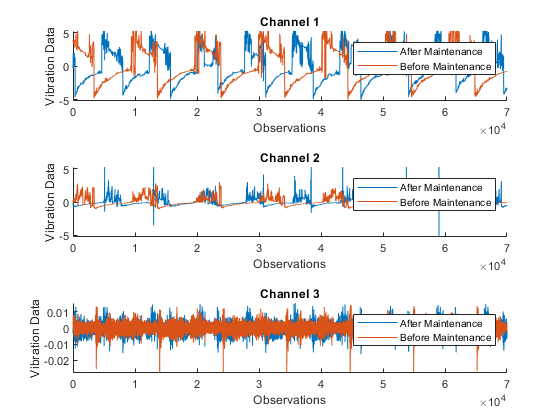

ensMember = 20;

plotVibrationData(trainData, ensMember)

## Extract Features with Diagnostic Feature Designer App

It is often challenging to determine which features to select and how important these features are. The [Diagnostic Feature Designer App](https://www.mathworks.com/help/predmaint/gs/explore-features-in-diagnostic-feature-designer.html) from the Predictive Maintenance Toolbox™ simplifies this workflow by interactively allowing you to explore your data visually by plotting and interacting with your ensemble members together, convert your data into different forms (time-domain vs frequency-domain), generate features of various types, and rank these features to establish which ones are the most effective. You can then generate a script that can re-process these features programmatically.

The following command will bring up the app, or you can find it in the Apps tab. 

Before you import the data, be sure to set `label` as a **condition variable**. This is because the data label identifies the condition of the machine: before maintenance vs. after maintenance, and we can examine these datasets separately. The goal is to train a model to differentiate between these two conditions.

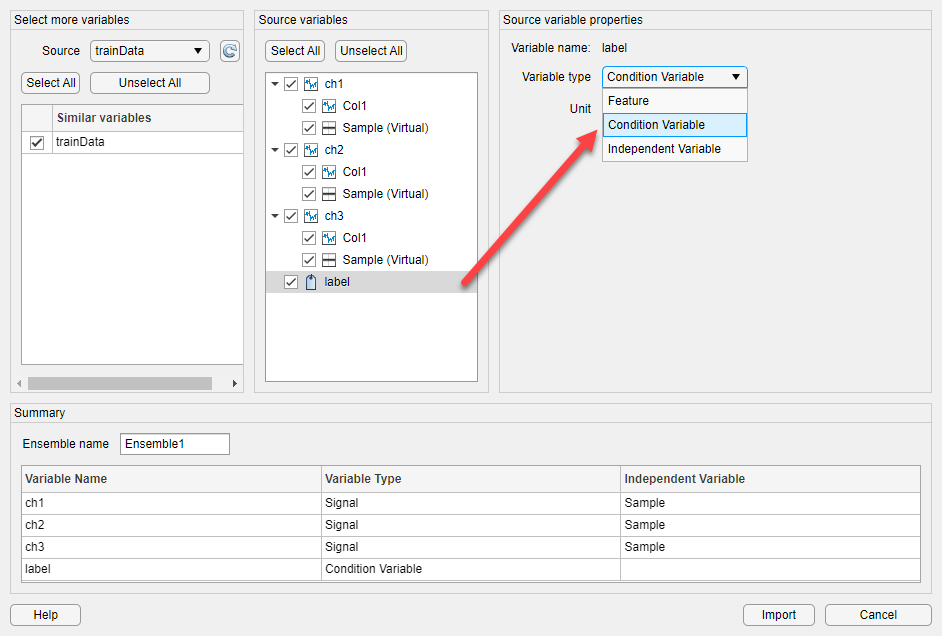

You can use the Diagnostic Feature Designer to iterate on the features. The features below were chosen using a progonostic ranking technique. 

- Ch1 : Crest Factor, Kurtosis, RMS, Std

- Ch2 : Mean, RMS, Skewness, Std

- Ch3 : Crest Factor, SINAD, SNR, THD

This visualization from the Diagnostic Feature Designer App shows the distributions separated by labels for various features extracted from Ch1 (**Note**: the histograms shown below are from a much larger version of this dataset, so the separation is more pronounced. The dataset included with this demo is a subset of the original data, so you may end up with slightly different feature rankings).

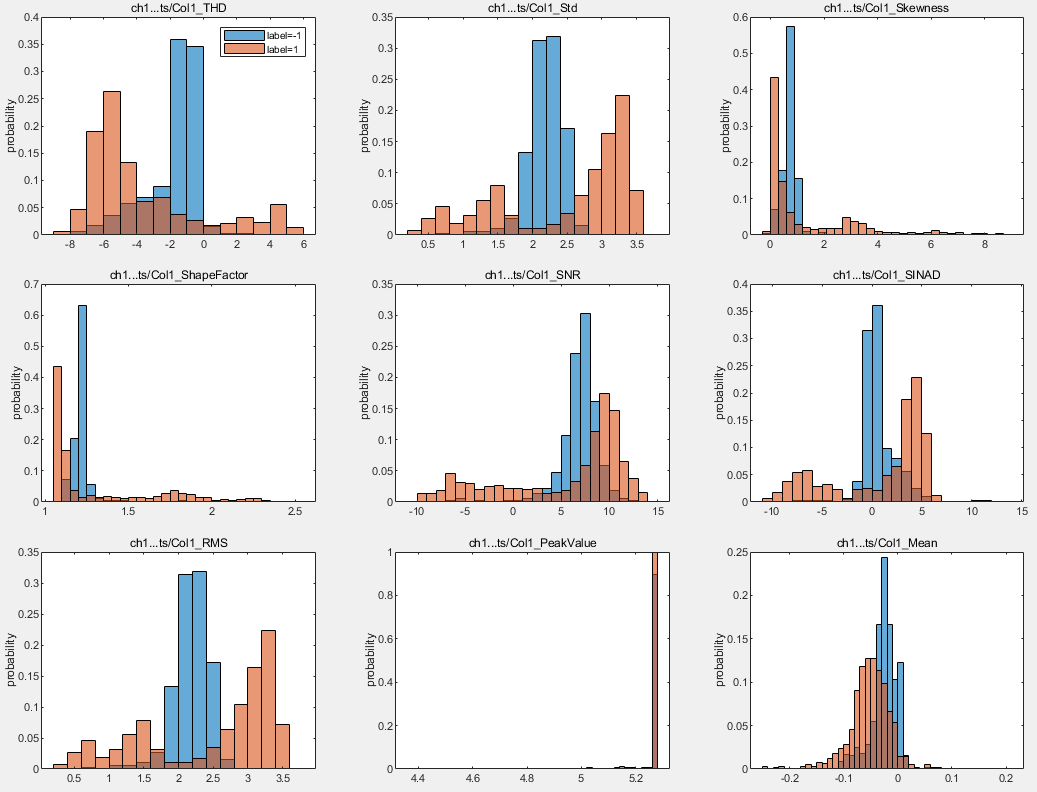

Once we've extracted and ranked the relevant features, we can generate a MATLAB® function from the app that will repeat the process that we just completed interactively.

trainFeatures = generateFeatures(trainData);

Copyright 2021 The MathWorks, Inc.